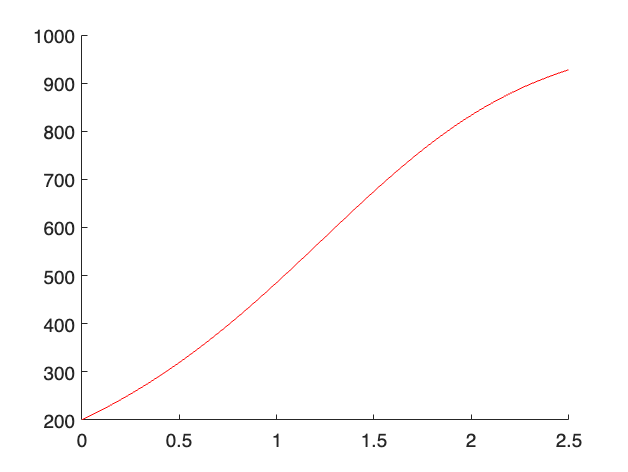

clear all
close all

%a. simulation

lambda=1;
theta=1e3;
alpha=2;

dNdt =@(N) lambda*N*(1-(N/theta)^alpha); 
dxdt = @(t,x)[dNdt(x(1));];

[T, X] = ode45(dxdt, [0,2.5], 200 );
hold on
plot(T, X, '-r')

hold off

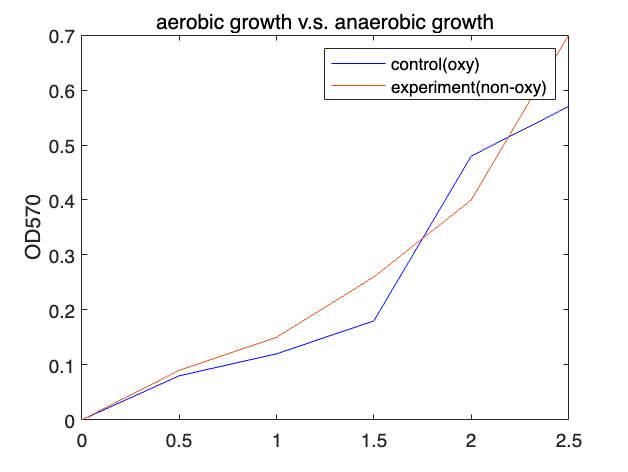

% b. load bacteria data
Ti=linspace(0,2.5,6);
Nexp=[0.00,0.09,0.15,0.26,0.40,0.70];
Nctr=[0.00,0.08,0.12,0.18,0.48,0.57];

plot(Ti,Nctr,"-b")
hold on
plot(Ti,Nexp,"-")
ylabel("OD570")
title("aerobic growth v.s. anaerobic growth")
legend("control(oxy)","experiment(non-oxy)")

% c. compute SSE
[Tsim,Xsim]=ode45(dxdt,Ti,0.08);
SSE=sum((Xsim.'-Nexp).^2)

SSE = 0.1343

% d. define a function
clear 
close all

SSE=bgrowthSSE(1,1,2)

SSE = 0.0304

% e. automated min algo-fminsearch
x0 = [1,1e3,3];
xmin = fminsearch(@(x) bgrowthSSE(x(1),x(2),x(3)),x0)

xmin = 1.0e+03 *

    0.0008    1.0435    0.0031




lambda=0.85;
theta=7.39;
alpha=14.48;
Ti=linspace(0,2.5,6);
Nexp=[0.00,0.09,0.15,0.26,0.40,0.70];

bgrowthSSE(lambda,theta,alpha)

ans = 0.0119

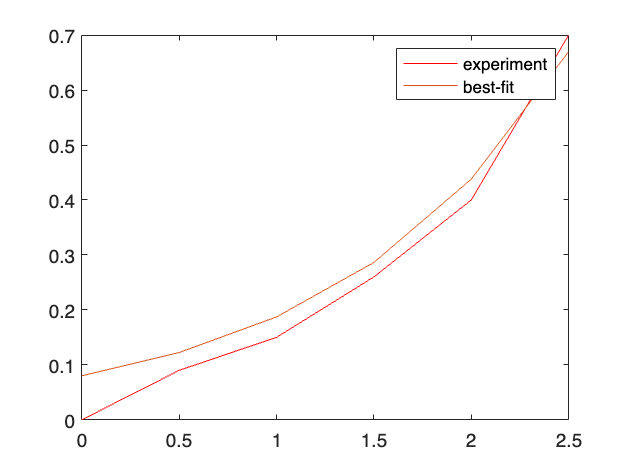


dNdt =@(N) lambda*N*(1-(N/theta)^alpha); 
dxdt = @(t,x)[dNdt(x(1));];
[Topsim,xopsim]= ode45(dxdt,Ti,0.08);
plot(Ti,Nexp,'-r')
hold on
plot(Ti,xopsim,'-')
legend("experiment","best-fit")